% img = imread('testimage.png');
% 
% [msg,detectedFormat,loc] = readBarcode(img);
% hold on;
% imshow(img);
% disp(msg);
ipAddress = '127.0.0.1'

ipAddress = '127.0.0.1'

rosshutdown;

Shutting down global node /matlab_global_node_00311 with NodeURI http://pk-Vector-GP66-12UE:33161/ and MasterURI http://127.0.0.1:11311.



rosinit(ipAddress);

Initializing global node /matlab_global_node_52634 with NodeURI http://pk-Vector-GP66-12UE:41499/ and MasterURI http://127.0.0.1:11311.


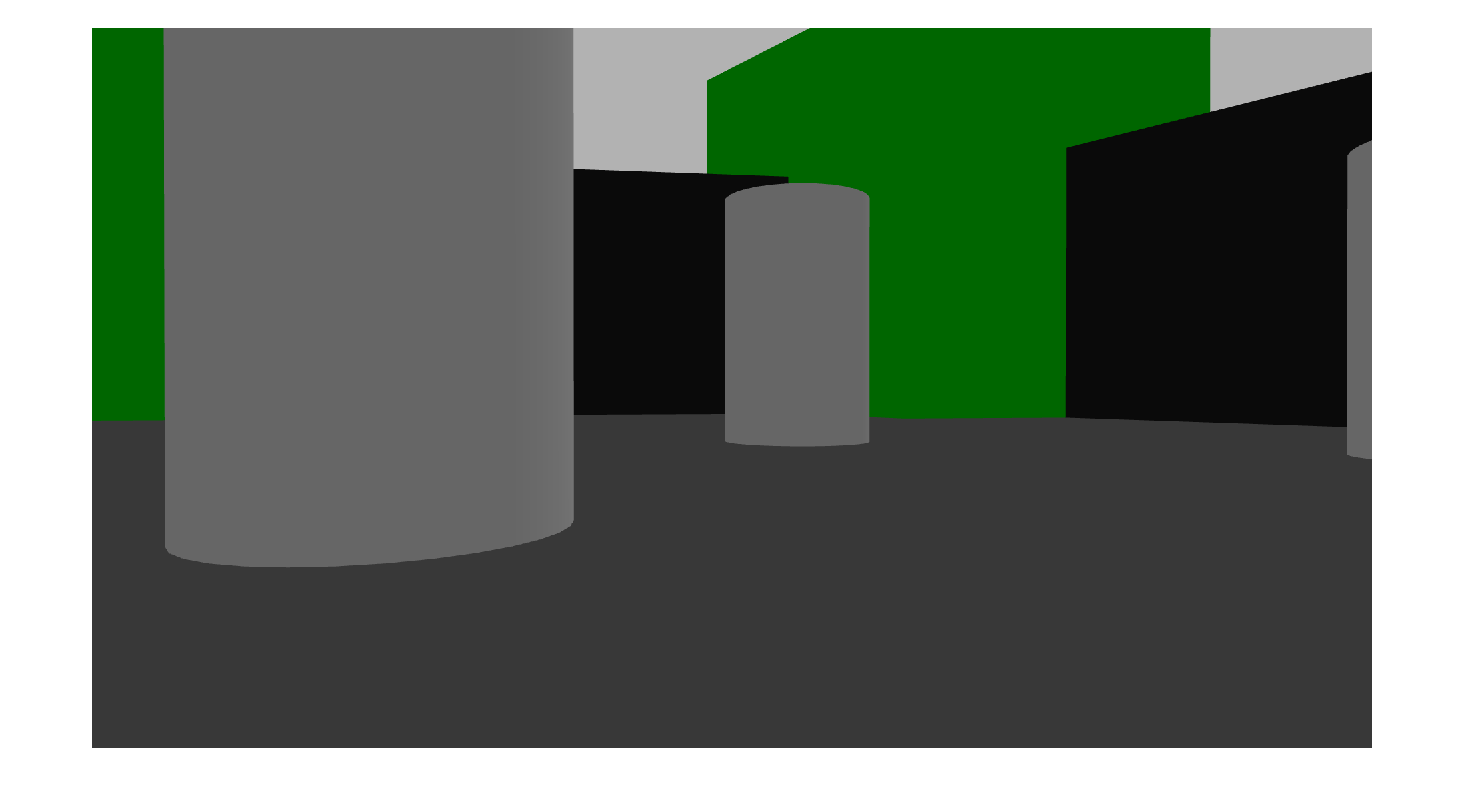

% rosinit;

% self.pub_vel = rospublisher('/cmd_vel','geometry_msgs/Twist');
% self.odom_ = rossubscriber('/odom','DataFormat','struct');
% self.lidar_ = rossubscriber('/scan','DataFormat','struct');
camera_rgb_ = rossubscriber('/camera/rgb/image_raw', 'sensor_msgs/Image');
% img_sub = rossubscriber("/camera/rgb/image_raw","DataFormat","struct");
% figure;
% img = imread('QR Code/FollowMe1.png')
% [msg,detectedFormat,loc] = readBarcode(img);
% disp(msg);
while 1
    msg= receive(camera_rgb_,10);
    img = readImage(msg);
    imshow(img);
end